clear all
close all

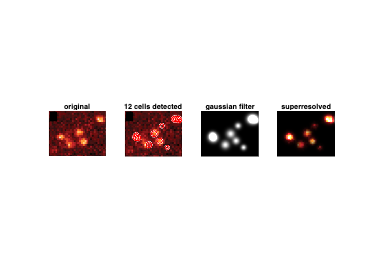

I = imread('Picture1.png');
%I_ = im2gray(I);
I_ = I;
%[T,EM] = graythresh(I);
%BW = imbinarize(I,0.7);
%figure;imshow(double(BW));
[center,radius] = imfindcircles(I_(:,:,1), [7 20],'ObjectPolarity','bright', ...
    'Sensitivity',0.89);
figure
subplot(141); imshow(I);title('original');
subplot(142)
imshow(I_)
hold on
h = viscircles(center,radius);
hold off
title(sprintf('%d cells detected',numel(radius)))
image = imread('Picture1.png'); % Replace 'your_image.jpg' with the path to your image
%image = im2gray(image);

filter = gaussian(size(image,1),size(image,2),  center(1,1),center(1,2),radius(1));
enhanced = double(image).*(filter);

for i=2:size(center,1)
    filter_i = gaussian(size(image,1),size(image,2), center(i,1),center(i,2),radius(i));
    enhanced_i = double(image).*(filter_i);
    filter = imadd(filter,filter_i,'double');
    enhanced = imadd(enhanced, enhanced_i, 'double');
    
end

subplot(143);imshow(filter); title('gaussian filter');
subplot(144);imshow(uint8(enhanced)); title('superresolved');
f=gcf;
exportgraphics(f,'result_orig.pdf')

function gaussianImage = gaussian(dim1,dim2, x0,y0,sigma)
    imageSize = [dim1, dim2];  % Size of the image
    
    % Generate grid of coordinates
    [X, Y] = meshgrid(1:imageSize(2), 1:imageSize(1));
    
    % Compute Gaussian distribution
    gaussianImage = (0.5./(pi.*(sigma.^2))).*exp(-((X-x0).^2 + (Y-y0).^2) / (2*sigma^2));
    gaussianImage = gaussianImage / max(gaussianImage(:));
end




